defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 8 - In vivo drug infusion');

%Examples for spatial analysis
filelist = loadFileList('.\Data\MRS2500 IP\*\*ICDetailAnalysis*');

load(filelist{3})
[peakStat, eventStats] = spatialPeakStats(smLIC, peaksBinaryL, smRIC, peaksBinaryR);

Left event rejected


h = plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat,[0 3000],1);

  0×1 empty cell array



figQuality(gcf,gca,[1.25 3])
export_fig('.\EPS Panels\baseline_spatial_analysis.eps')

h = plotTimeSeries_dFoF(smLIC, smRIC, peaksBinaryL, peaksBinaryR, peakStat,[6000 9000],1);

  0×1 empty cell array



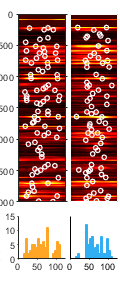

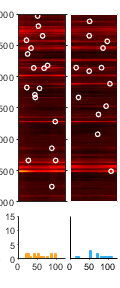

figQuality(gcf,gca,[1.25 3])
export_fig('.\EPS Panels\MRSIP_spatial_analysis.eps')